# Estimating the value of Pi using Monte Carlo

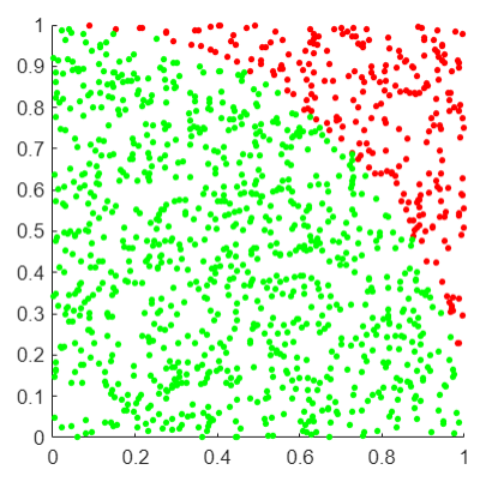

#### Define function

function PI = computePi_slow(n)
    c = 0;
    for i = 1:n
        r = rand^2 + rand^2;
        c = c + sum(r<=1);
    end
    
    PI = 4/n * c;
end

N = 1e8;

tic
PI = computePi_slow(N)

PI = 3.1416

for_time = toc

for_time = 3.1478

#### Use vectorization to improve performance

function PI = computePi(n)
    r = rand(1,n).^2 + rand(1,n).^2;
    c = sum(r<=1);
    PI = 4/n * c;
end

tic
PI = computePi(N)

PI = 3.1418

vec_time = toc

vec_time = 1.0002

fprintf("Speedup: %.2fx",for_time/vec_time)

Speedup: 3.15x

#### Learn more

[MATLAB Coding Practices for Efficiency and Performance | Self-Paced Online Courses ](https://matlabacademy.mathworks.com/details/matlab-coding-practices-for-efficiency-and-performance/otmlcep)